        %% Q.5 - HW3 %%
% tidying up
clc;    % clear the command window
clear;  % clear the workspace
close all; % close all opened figures

% Load the data
data = readtimetable('ASX200.xlsx');

head(data,5); % check

       Date        AXJO_Close    Adj_Returns
    ___________    __________    ___________

    04-Oct-2019      6517.1       0.0071097 
    06-Oct-2019      6563.6       0.0045299 
    07-Oct-2019      6593.4       -0.007108 
    08-Oct-2019      6546.7      6.1083e-05 
    09-Oct-2019      6547.1       0.0090772 



tail(data,5); % check 

       Date        AXJO_Close    Adj_Returns
    ___________    __________    ___________

    29-Aug-2024      8045.1        0.0058003
    30-Aug-2024      8091.9         0.002222
    02-Sep-2024      8109.9      -0.00082646
    03-Sep-2024      8103.2        -0.019024
    04-Sep-2024      7950.5              NaN




% ARMA(5,5)
tp = 6; %(0,..5)
tq = 6; %(0,..5)

% creating matrix for MSE and k (nb of parameters)
MSE = zeros(tp,tq);
k = zeros(tp,tq);

% specify and estimate each ARMA(p,q) model
y = data.Adj_Returns;
T = numel(y);

for p = 0:tp-1
    for q = 0:tq-1
        model = arima(p,0,q);
        [estmd1,~,~] = estimate(model, y, 'display', 'off');
        resid = infer(estmd1,y);

        % compute nb of parameters
        k(p+1,q+1) = p+q+1;

        % MSE - mean squared errors
        MSE(p+1, q+1) = mean(resid.^2);
    end
end
MSE = reshape(MSE,tp*tq,1);
k = reshape(k,tp*tq,1);

% Construct AIC, HQIC, and BIC
aic = exp(2*k/T).*MSE; % ".*" element-wise multiplication
hqic = (log(T)).^(2*k/T).*MSE;
bic = (sqrt(T)).^(2*k/T).*MSE;

% AIC
aic = reshape (aic,tp,tq)

aic = 1.0e-03 *

    0.1245    0.1219    0.1206    0.1206    0.1206    0.1200
    0.1213    0.1217    0.1204    0.1191    0.1193    0.1199
    0.1211    0.1223    0.1220    0.1209    0.1190    0.1201
    0.1201    0.1193    0.1188    0.1190    0.1191    0.1191
    0.1202    0.1227    0.1189    0.1192    0.1188    0.1208
    0.1197    0.1199    0.1201    0.1190    0.1190    0.1209


[r,c] = find(aic == min(min(aic)));
disp(min(min(aic)));

   1.1881e-04



best_p = r-1;

Best model in AIC: ARMA(4,4)


hqic = 1.0e-03 *

    0.1247    0.1223    0.1211    0.1213    0.1215    0.1211
    0.1217    0.1223    0.1212    0.1200    0.1204    0.1212
    0.1217    0.1231    0.1229    0.1221    0.1203    0.1216
    0.1209    0.1202    0.1200    0.1203    0.1206    0.1208
    0.1211    0.1238    0.1202    0.1207    0.1205    0.1226
    0.1208    0.1212    0.1216    0.1207    0.1209    0.1230


r = 4

c = 3

   1.1995e-04



best_p = 3

best_q = 2

Best model in HQIC: ARMA(3,2)


bic = 1.0e-03 *

    0.1250    0.1229    0.1221    0.1226    0.1231    0.1230
    0.1223    0.1232    0.1224    0.1215    0.1222    0.1234
    0.1226    0.1243    0.1245    0.1240    0.1225    0.1241
    0.1221    0.1218    0.1218    0.1225    0.1231    0.1236
    0.1227    0.1258    0.1224    0.1232    0.1233    0.1258
    0.1227    0.1234    0.1241    0.1235    0.1241    0.1266


r = 2

c = 4

   1.2155e-04



best_p = 1

best_q = 3

Best model in BIC: ARMA(1,3)


best_q = c-1;
fprintf('Best model in AIC: ARMA(%d,%d)\n', best_p, best_q);

% HQIC
hqic = reshape (hqic,tp,tq)
[r,c] = find(hqic == min(min(hqic)))
disp(min(min(hqic)));
best_p = r-1
best_q = c-1
fprintf('Best model in HQIC: ARMA(%d,%d)\n', best_p, best_q);

% BIC
bic = reshape (bic,tp,tq)
[r,c] = find(bic == min(min(bic)))
disp(min(min(bic)));
best_p = r-1
best_q = c-1
fprintf('Best model in BIC: ARMA(%d,%d)\n', best_p, best_q);

% I would choose AIC and BIC, since these two are the most
% widely used models. Between these two, BIC is the best since it picks
% smaller models, which is generally good for forecasting.

% GARCH(1,1) model construction
% ARMA(1,3)
tp = 2; %(0,..1)
tq = 4; %(0,..3)

for p = 0:tp-1
    for q = 0:tq-1
        model_g = arima(p,0,q);
        [estmd1,~,~] = estimate(model_g, y, 'display', 'off');
        resid_g = infer(estmd1,y);
    end
end

garch_m = garch(1,1);
fit = estimate(garch_m,resid_g);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    5.0868e-06     1.5735e-06        3.2327        0.0012261
    GARCH{1}       0.81624       0.024646        33.118      1.6234e-240
    ARCH{1}        0.13051        0.01458        8.9516       3.5052e-19



disp(fit);

  garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 5.08677e-06
           GARCH: {0.816242} at lag [1]
            ARCH: {0.130514} at lag [1]
          Offset: 0



% Plot the conditional volatility

% Estimate the conditional variances (volatility squared)
variances = infer(fit, resid_g); % This gives you the conditional variances

% Calculate conditional volatility (the square root of variances)
conditionalVolatility = sqrt(variances);
%disp(conditionalVolatility);    % display
mean_CV = mean(conditionalVolatility);    % mean
disp(mean_CV);

    0.0096



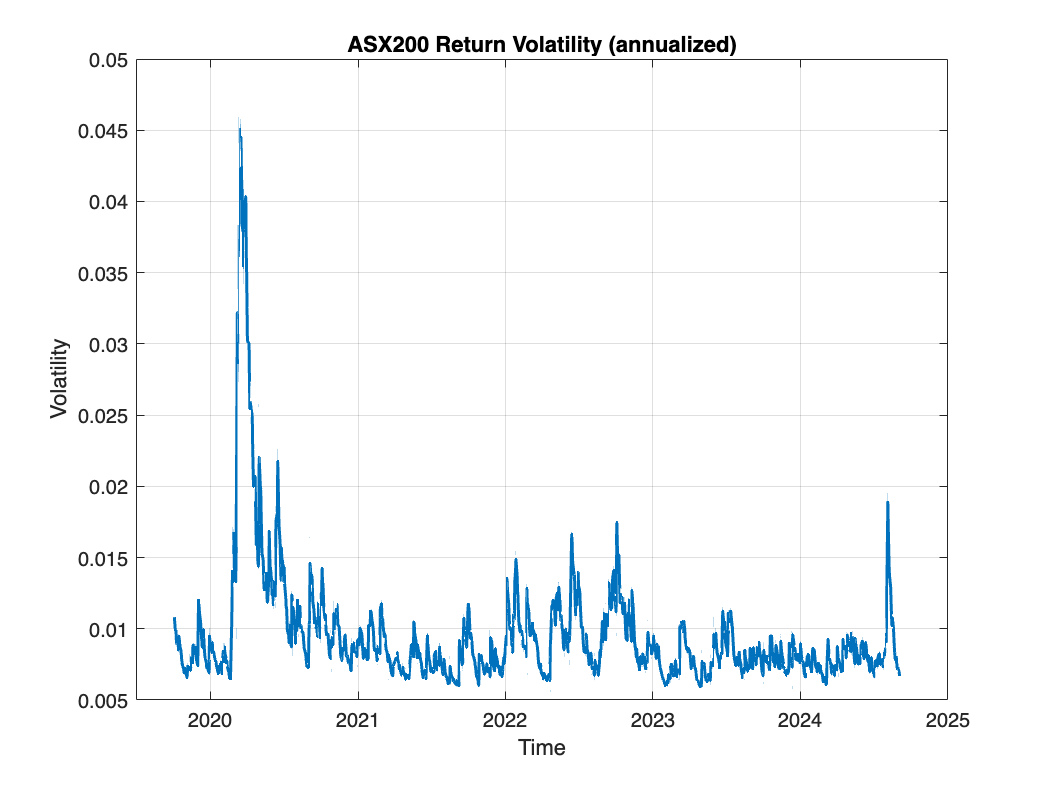


% Plot conditional volatility
figure;
plot(data.Date(1:end-1), conditionalVolatility, 'LineWidth', 1.5);
title('ASX200 Return Volatility (annualized)');
xlabel('Time');
ylabel('Volatility');
grid on;